% %发射信号
f0 = 17300;
f = [];
fs = 48000;
% A1 =300;
% A2 = 300;
A1 = 350;
A2 = 350;

time=4800;
N=8;
gap=700;


for i=1:N
    f = [f f0+(i-1)*gap];
end

t = 0:1/fs:(time-1)/fs;
sendSignal = zeros(1, time);
for i=1:N
    
    
    if i<5
        A=A2;
    else
        A=A1;
    end
    f(i)
    A
    sendSignal = sendSignal + A*cos(2*pi*f(i)*t);
    
end

ans = 17300

A = 350

ans = 18000

A = 350

ans = 18700

A = 350

ans = 19400

A = 350

ans = 20100

A = 350

ans = 20800

A = 350

ans = 21500

A = 350

ans = 22200

A = 350

sendSignal = sendSignal'

sendSignal = 1.0e+03 *

    2.8000
   -2.3257
    1.1320
    0.2231
   -1.1628
    1.3934
   -1.0231
    0.4414
   -0.0526
    0.0397


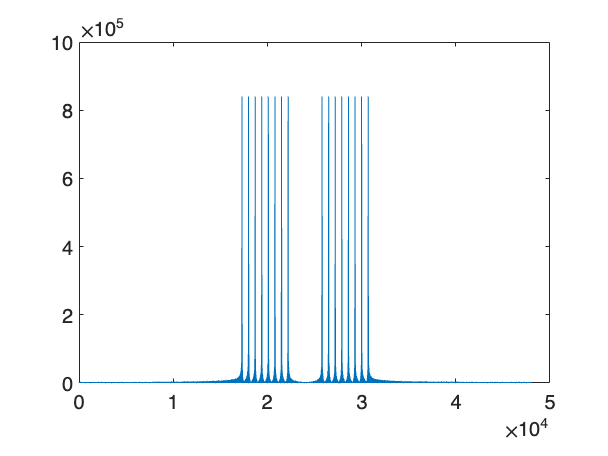

plot(abs(fft(sendSignal,48000)))

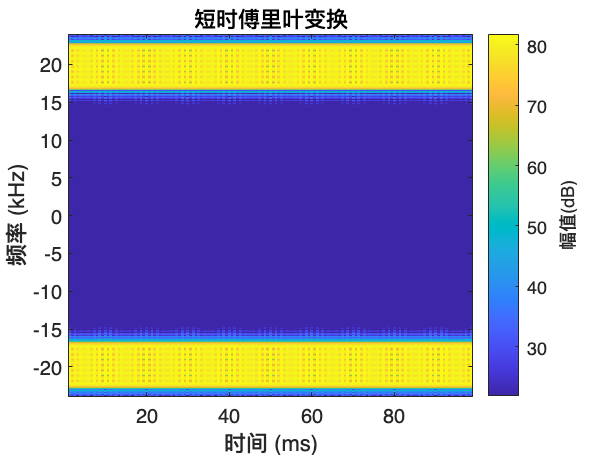

stft((sendSignal), 48000, "FFTLength", 1024)


dlmwrite("send/multi8a.txt", sendSignal)


% single-frefix
% t = 0:1/fs:(time-1)/fs;
% 
% sendSignal=A*cos(2*pi*f0*t);
% sendSignal = sendSignal'
% plot(abs(fft(sendSignal,48000)))
% stft((sendSignal), 48000)
% dlmwrite("send/frefix.txt ", sendSignal)



% fmcw
% tm=2e-2;
% bw = [16000,23000];
% fs=48000;
% time=960;
% t = 0:1/fs:(time-1)/fs;
% signal  = chirp(t,16000,0.02,23000);
% sendSignal=[];
% for i=1:5
%     sendSignal= [sendSignal signal];
% end
% 
% 
% sendSignal = sendSignal'
% plot(abs(fft(sendSignal,48000)))
% stft((sendSignal), 48000, 'FFTLength', 1024)
% dlmwrite("send/fmcw.txt ", sendSignal)
